# **COMP0053 EmoPain Data Analysis**

The data files are .mat files, and each file corresponds to a participant with chronic pain (‘P’ prefix in filename) or a healthy control participant (‘C’ prefix in filename) with integer id # evident in the file name. Each file has suffix ‘N’ or ‘D’ in its name to indicate the level of challenge of the exercise performed in the corresponding file, ‘normal’ or ‘difficult’ respectively.

Each file contains the body movement data for a single participant for all exercise sessions under one challenge level (‘normal’ or ‘difficult’), in a T × 78 matrix, where T is the number of data samples for that file.

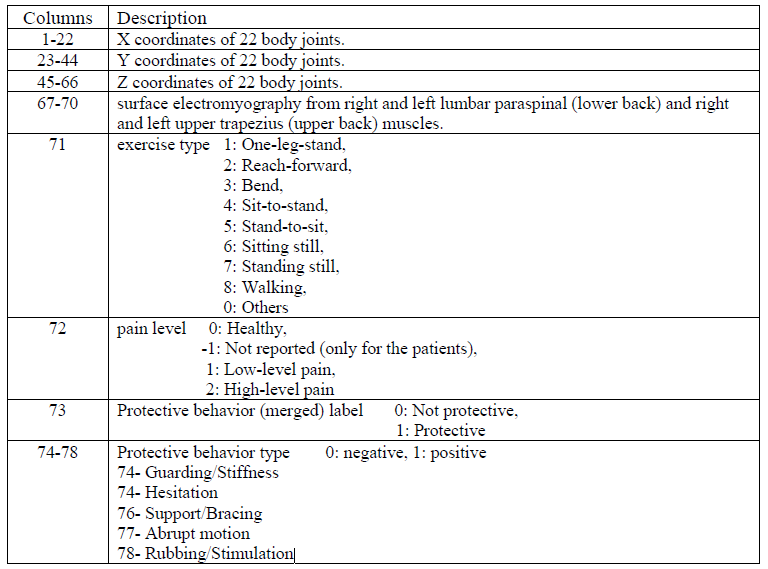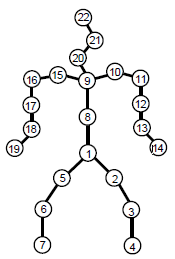

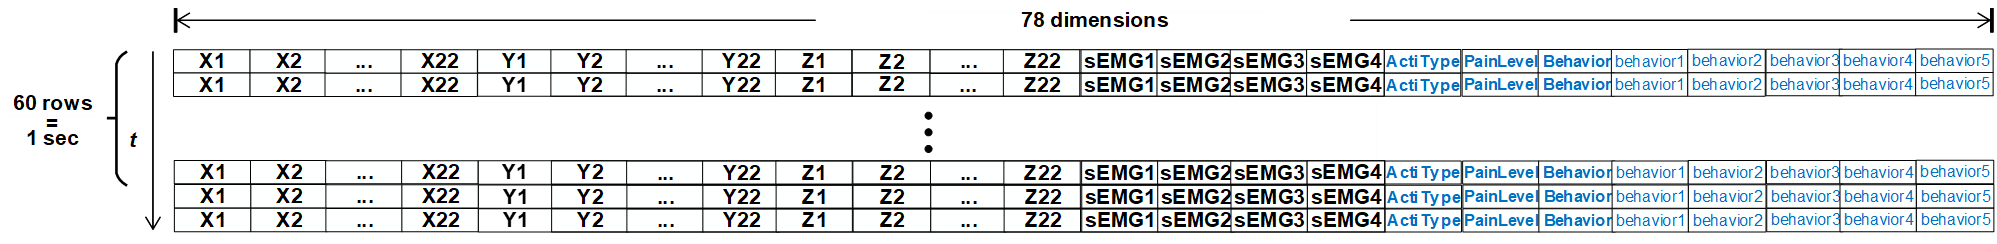

## **Training and validation data**

*****All sEMG figures are zipped in Figures_Final.zip*****

load("train.mat");
load("validation.mat");
train = {C382D, C382N, C544D, C56D, C709N, C788N, C93D, P113D, P113N, P191D, P191N, P299D, P299N, P300D, P336D, P492D, P492N, P531N, P699D, P699N, P890N, P921D, P921N};
Participant_IDs = ["C382D", "C382N", "C544D", "C56D", "C709N", "C788N", "C93D", "P113D", "P113N", "P191D", "P191N", "P299D", "P299N", "P300D", "P336D", "P492D", "P492N", "P531N", "P699D", "P699N", "P890N", "P921D", "P921N"];

CXN     = {C382N, C709N, C788N, C202N, C256N};
CXN_ID  = ["C382N", "C709N", "C788N", "C202N", "C256N"];
CXD     = {C382D, C544D, C56D, C93D, C202D, C256D, C67D};
CXD_ID  = ["C382D", "C544D", "C56D", "C93D", "C202D", "C256D", "C67D"];
PXN     = {P113N, P191N, P299N, P492N, P531N, P699N, P890N, P921N, P342N, P487N, P54N, P649N};
PXN_ID  = ["P113N", "P191N", "P299N", "P492N", "P531N", "P699N", "P890N", "P921N", "P342N", "P487N", "P54N", "P649N"];
PXD     = {P113D, P191D, P299D, P300D, P336D, P492D, P699D, P921D, P342D, P487D, P54D};
PXD_ID  = ["P113D", "P191D", "P299D", "P300D", "P336D", "P492D", "P699D", "P921D", "P342D", "P487D", "P54D"];

## Control participant, Normal exercise

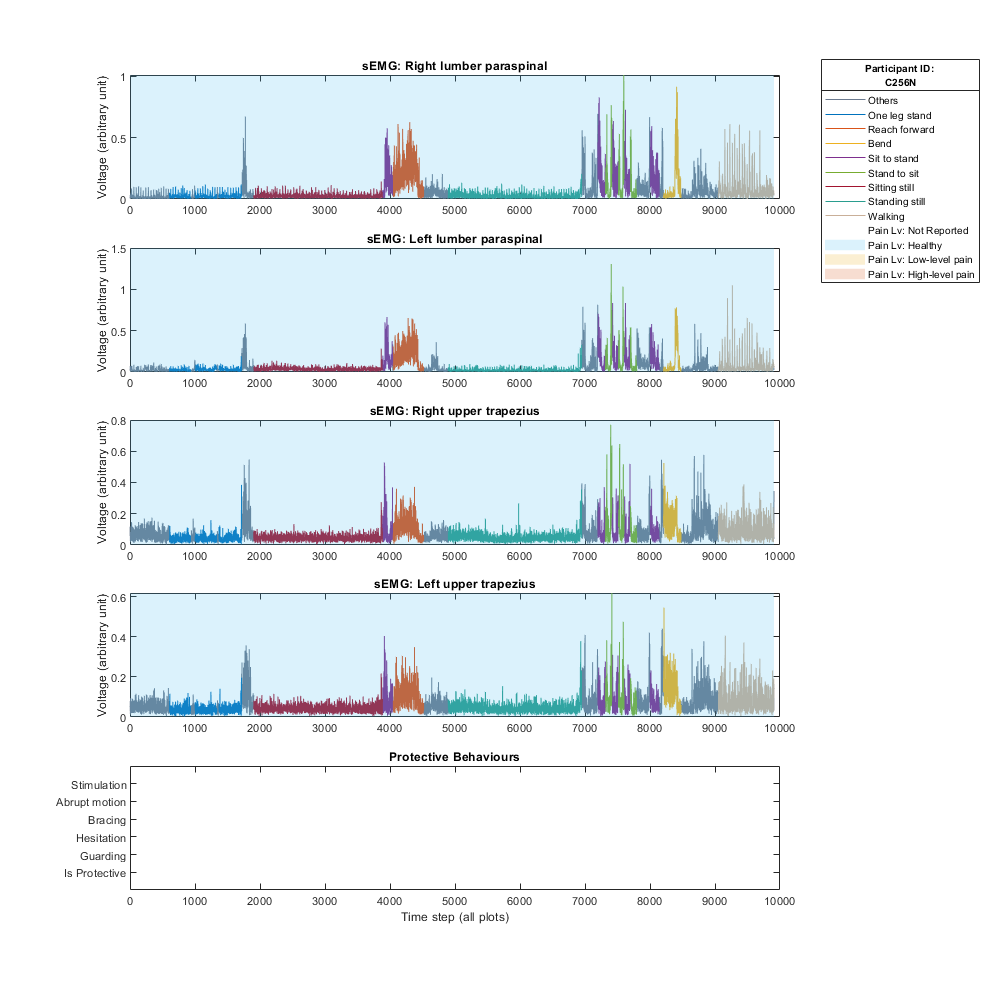

category = 'CXN';
[experiment_time_steps, experiment_duration, Protective_and_pain_Prob, Mean_Table] = M_Analysis(category, CXN, CXN_ID);

% Mean experiment duration
CXN_Mean_time_step      = mean(experiment_time_steps);
CXN_Mean_time_duration  = mean(experiment_duration);
fprintf('The mean duration of %s is %f +- %f seconds. \n', category, CXN_Mean_time_duration, std(experiment_duration));

The mean duration of CXN is 178.273333 +- 17.888146 seconds. 


Protective_and_pain_Prob_Table = array2table(Protective_and_pain_Prob, 'VariableName', {'P(trigger Protec. Be)', 'P(Not Recorded pain)', 'P(Healthy pain)', 'P(Low Level pain)', 'P(High Level pain)'});
Protective_and_pain_Prob_Table

Protective_and_pain_Prob_Table = 1×5 table
    P(trigger Protec. Be)    P(Not Recorded pain)    P(Healthy pain)    P(Low Level pain)    P(High Level pain)
    _____________________    ____________________    _______________    _________________    __________________

              0                       0                     1                   0                    0         


Mean_Table

Mean_Table = 1×432 table
    Not_Protective_behavior_Not_Recorded_pain_Others    Not_Protective_behavior_Not_Recorded_pain_One_leg_stand    Not_Protective_behavior_Not_Recorded_pain_Reach_forward    Not_Protective_behavior_Not_Recorded_pain_Bend    Not_Protective_behavior_Not_Recorded_pain_Sit_to_stand    Not_Protective_behavior_Not_Recorded_pain_Stand_to_sit    Not_Protective_behavior_Not_Recorded_pain_Sitting_still    Not_Protective_behavior_Not_Recorded_pain_Standing_still    Not_Protective_behavior_Not_Recorded_pain_Walking    Not_Protective_behavior_Healthy_pain_Others    Not_Protective_behavior_Healthy_pain_One_leg_stand    Not_Protective_behavior_Healthy_pain_Reach_forward    Not_Protective_behavior_Healthy_pain_Bend    Not_Protective_behavior_Healthy_pa

## Control participant, Difficult exercise

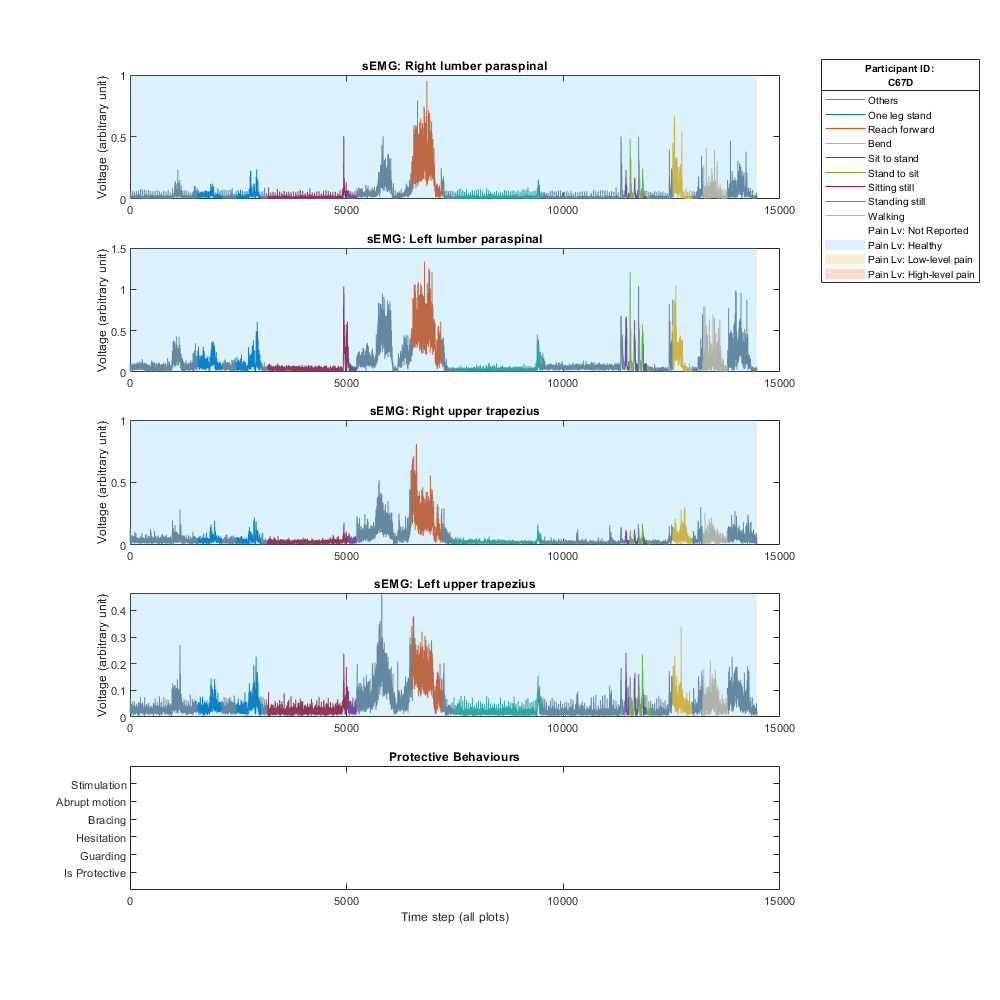

category = 'CXD';
[experiment_time_steps, experiment_duration, Protective_and_pain_Prob, Mean_Table] = M_Analysis(category, CXD, CXD_ID);

% Mean experiment duration
CXD_Mean_time_step      = mean(experiment_time_steps);
CXD_Mean_time_duration  = mean(experiment_duration);
fprintf('The mean duration of %s is %f +- %f seconds. \n', category, CXD_Mean_time_duration, std(experiment_duration));

The mean duration of CXD is 213.323810 +- 18.011179 seconds. 


Protective_and_pain_Prob_Table = array2table(Protective_and_pain_Prob, 'VariableName', {'P(trigger Protec. Be)', 'P(Not Recorded pain)', 'P(Healthy pain)', 'P(Low Level pain)', 'P(High Level pain)'});
Protective_and_pain_Prob_Table

Protective_and_pain_Prob_Table = 1×5 table
    P(trigger Protec. Be)    P(Not Recorded pain)    P(Healthy pain)    P(Low Level pain)    P(High Level pain)
    _____________________    ____________________    _______________    _________________    __________________

              0                       0                     1                   0                    0         


Mean_Table

Mean_Table = 1×432 table
    Not_Protective_behavior_Not_Recorded_pain_Others    Not_Protective_behavior_Not_Recorded_pain_One_leg_stand    Not_Protective_behavior_Not_Recorded_pain_Reach_forward    Not_Protective_behavior_Not_Recorded_pain_Bend    Not_Protective_behavior_Not_Recorded_pain_Sit_to_stand    Not_Protective_behavior_Not_Recorded_pain_Stand_to_sit    Not_Protective_behavior_Not_Recorded_pain_Sitting_still    Not_Protective_behavior_Not_Recorded_pain_Standing_still    Not_Protective_behavior_Not_Recorded_pain_Walking    Not_Protective_behavior_Healthy_pain_Others    Not_Protective_behavior_Healthy_pain_One_leg_stand    Not_Protective_behavior_Healthy_pain_Reach_forward    Not_Protective_behavior_Healthy_pain_Bend    Not_Protective_behavior_Healthy_pa

## Chronic pain participant, Normal exercise

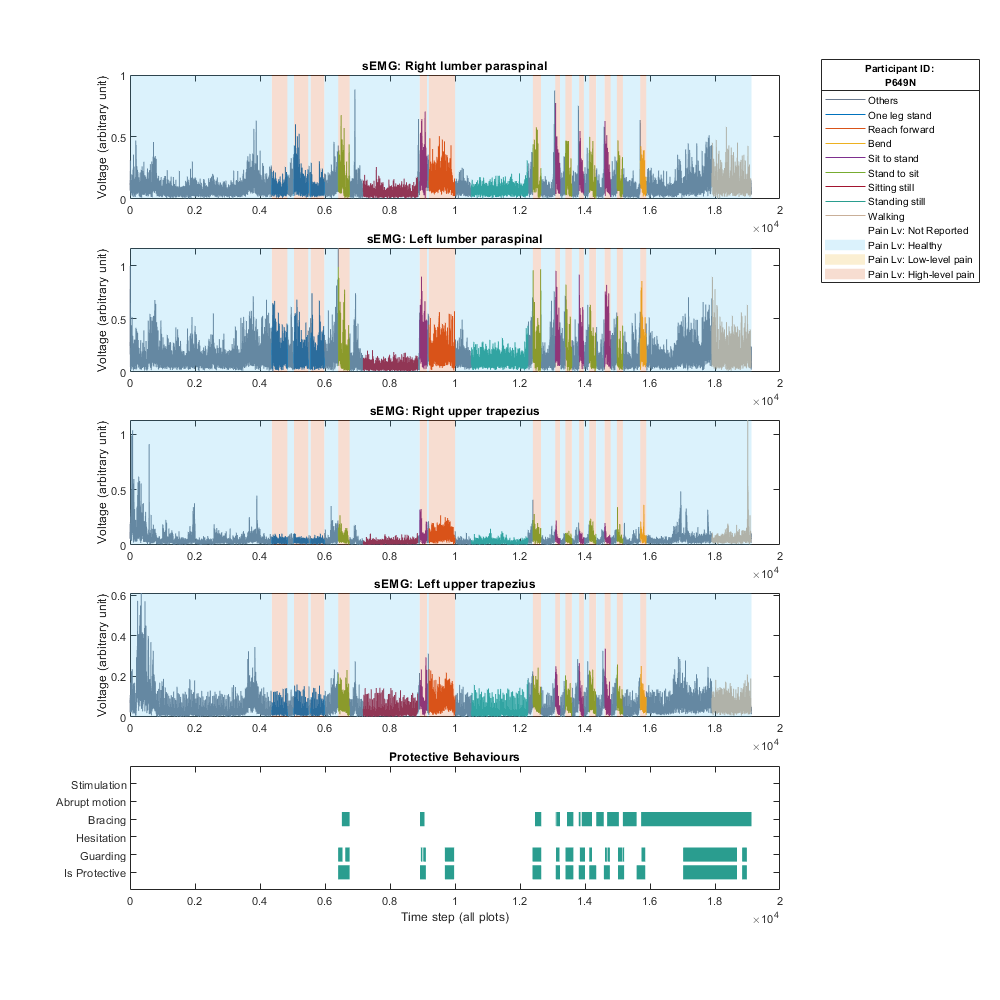

category = 'PXN';
[experiment_time_steps, experiment_duration, Protective_and_pain_Prob, Mean_Table] = M_Analysis(category, PXN, PXN_ID);

% Mean experiment duration
PXN_Mean_time_step      = mean(experiment_time_steps);
PXN_Mean_time_duration  = mean(experiment_duration);
fprintf('The mean duration of %s is %f +- %f seconds. \n', category, PXN_Mean_time_duration, std(experiment_duration));

The mean duration of PXN is 263.083333 +- 64.357709 seconds. 


Protective_and_pain_Prob_Table = array2table(Protective_and_pain_Prob, 'VariableName', {'P(trigger Protec. Be)', 'P(Not Recorded pain)', 'P(Healthy pain)', 'P(Low Level pain)', 'P(High Level pain)'});
Protective_and_pain_Prob_Table

Protective_and_pain_Prob_Table = 1×5 table
    P(trigger Protec. Be)    P(Not Recorded pain)    P(Healthy pain)    P(Low Level pain)    P(High Level pain)
    _____________________    ____________________    _______________    _________________    __________________

          0.052475                 0.50471               0.25387             0.15632              0.085106     


Mean_Table

Mean_Table = 1×432 table
    Not_Protective_behavior_Not_Recorded_pain_Others    Not_Protective_behavior_Not_Recorded_pain_One_leg_stand    Not_Protective_behavior_Not_Recorded_pain_Reach_forward    Not_Protective_behavior_Not_Recorded_pain_Bend    Not_Protective_behavior_Not_Recorded_pain_Sit_to_stand    Not_Protective_behavior_Not_Recorded_pain_Stand_to_sit    Not_Protective_behavior_Not_Recorded_pain_Sitting_still    Not_Protective_behavior_Not_Recorded_pain_Standing_still    Not_Protective_behavior_Not_Recorded_pain_Walking    Not_Protective_behavior_Healthy_pain_Others    Not_Protective_behavior_Healthy_pain_One_leg_stand    Not_Protective_behavior_Healthy_pain_Reach_forward    Not_Protective_behavior_Healthy_pain_Bend    Not_Protective_behavior_Healthy_pa

## Chronic pain participant, Difficult exercise

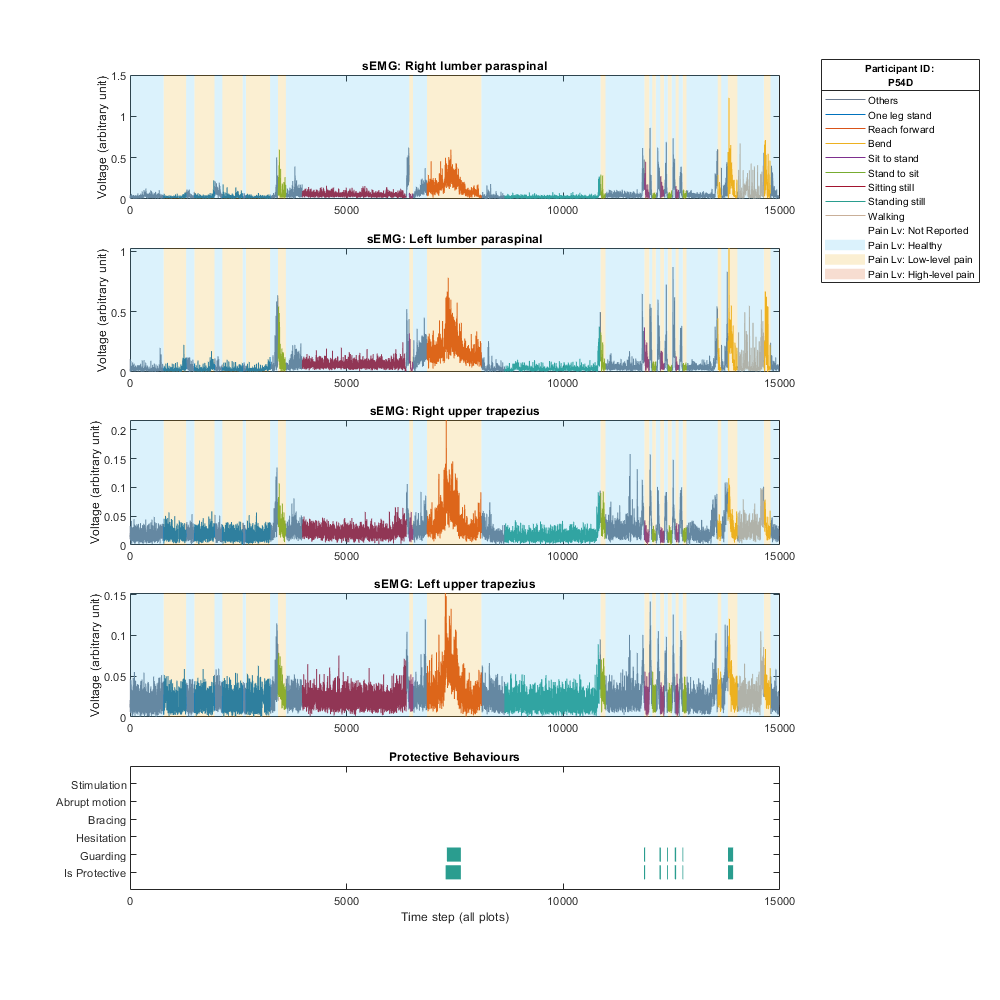

category = 'PXD';
[experiment_time_steps, experiment_duration, Protective_and_pain_Prob, Mean_Table] = M_Analysis(category, PXD, PXD_ID);

% Mean experiment duration
PXD_Mean_time_step      = mean(experiment_time_steps);
PXD_Mean_time_duration  = mean(experiment_duration);
fprintf('The mean duration of %s is %f +- %f seconds. \n', category, PXD_Mean_time_duration, std(experiment_duration));

The mean duration of PXD is 275.828788 +- 50.256928 seconds. 


Protective_and_pain_Prob_Table = array2table(Protective_and_pain_Prob, 'VariableName', {'P(trigger Protec. Be)', 'P(Not Recorded pain)', 'P(Healthy pain)', 'P(Low Level pain)', 'P(High Level pain)'});
Protective_and_pain_Prob_Table

Protective_and_pain_Prob_Table = 1×5 table
    P(trigger Protec. Be)    P(Not Recorded pain)    P(Healthy pain)    P(Low Level pain)    P(High Level pain)
    _____________________    ____________________    _______________    _________________    __________________

          0.071823                  0.5194               0.19648             0.20726              0.076863     


Mean_Table

Mean_Table = 1×432 table
    Not_Protective_behavior_Not_Recorded_pain_Others    Not_Protective_behavior_Not_Recorded_pain_One_leg_stand    Not_Protective_behavior_Not_Recorded_pain_Reach_forward    Not_Protective_behavior_Not_Recorded_pain_Bend    Not_Protective_behavior_Not_Recorded_pain_Sit_to_stand    Not_Protective_behavior_Not_Recorded_pain_Stand_to_sit    Not_Protective_behavior_Not_Recorded_pain_Sitting_still    Not_Protective_behavior_Not_Recorded_pain_Standing_still    Not_Protective_behavior_Not_Recorded_pain_Walking    Not_Protective_behavior_Healthy_pain_Others    Not_Protective_behavior_Healthy_pain_One_leg_stand    Not_Protective_behavior_Healthy_pain_Reach_forward    Not_Protective_behavior_Healthy_pain_Bend    Not_Protective_behavior_Healthy_pa